**Image Adjustment Notebook**

**Kuan-Min Lee**

**Relative MATLAB Function:**

**imadjust(I,[low_in high_in], [low_out high_out], gamma);**

**Basic Theory Explanation:**

It maps intensity values in I to **new values, where gama function specifies the shape of the curve** d**escribing relationship between I and the new value:**

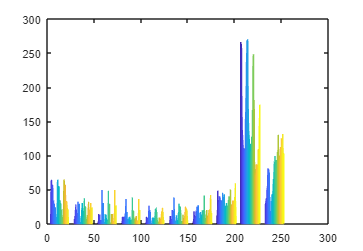

car_img=imread("car.jpg"); % read in sample image
figure(1);
hist(double(car_img))

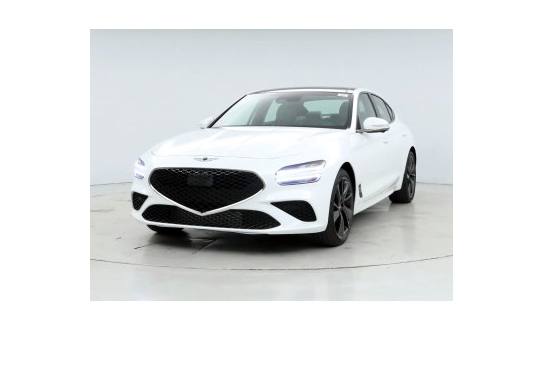

figure(2)
imshow(car_img)

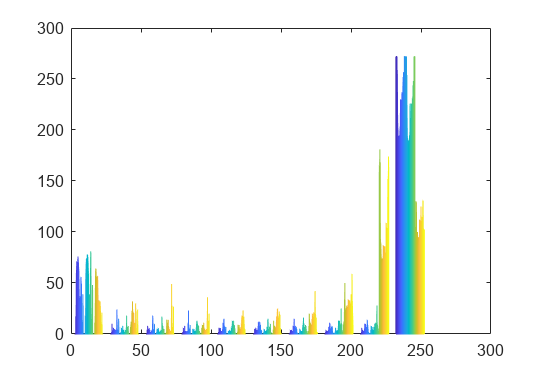

car_img_new=imadjust(car_img,[.2 .3 0; .6 .7 1],[]);
figure(3)
hist(double(car_img_new))

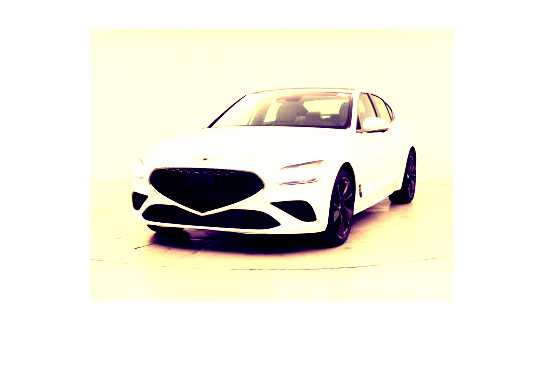

figure(4)
imshow(car_img_new)

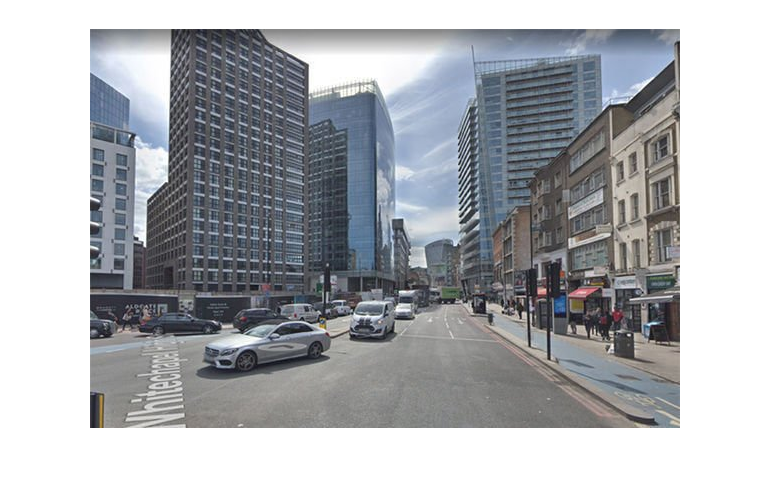

map_img=imread("google-maps-how-to-get-street-view-google-maps-2421144.jpg");
map_img_new=imadjust(map_img,[.2 .3 0; .6 .7 1],[]);
figure(5)
imshow(map_img)

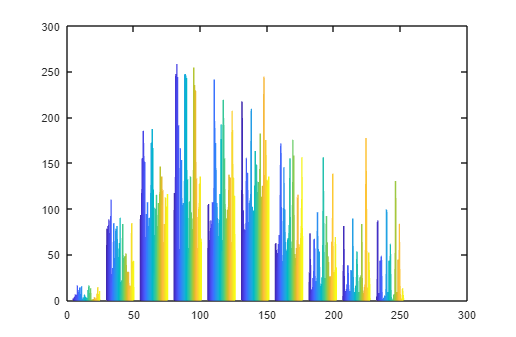

figure(6)
hist(double(map_img))

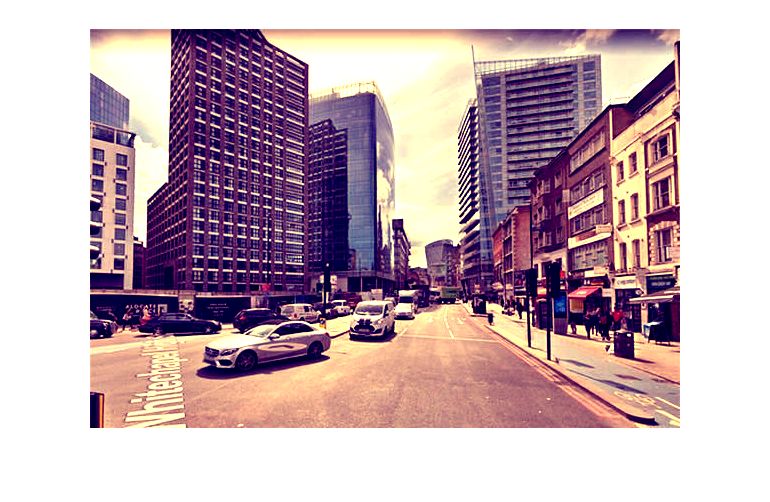

figure(7)
imshow(map_img_new)

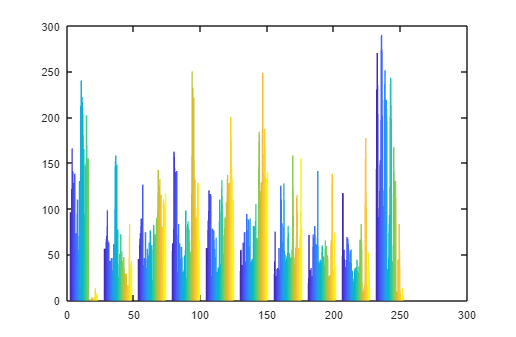

figure(8)
hist(double(map_img_new))

**Features of such image function:**

- **It does enlarge the dispersion of the distribution of pixel value to make the image more contrast to audiences**

- Also due to this mechanism, the pixel value gets stretched in each color channel, which might introduce some **artificail color to the image (see the sky portion of the map image and background of the car image)**

**Possible Usage:**

- **Relatively uniform colored images**

- **Grayscale images**

**As we adapt this method to typcial color image, we need to pay attention to the artificial colors it produce along the way. **